# 4BM00-Assingment 4

[https://nl.mathworks.com/help/images/morphological-filtering.html](https://nl.mathworks.com/help/images/morphological-filtering.html)

- Load 1 image and find a suitable threshold to transform grayscale image into black white image.

- Keypoint: find a way to identify edge with threshold analysis to targeted image file.

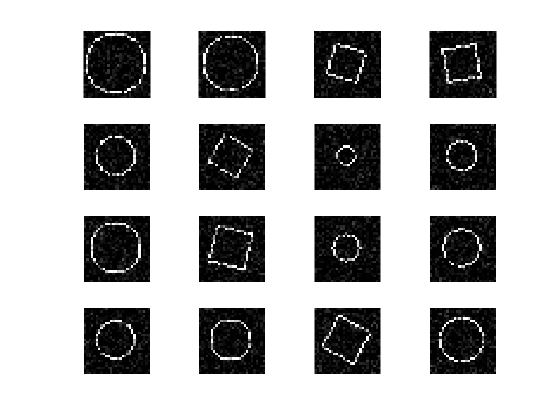

clc; clear all; clear figure; clear var
% df1=imread('Images\Image0001.tiff');
patern=load('Images\Labels.mat');pat=struct2table(patern);
% ex=patern.Labels;
dc = dir('Images\*.tiff');dct=struct2table(dc);
Image_table=[dct pat];%make table and concatenate the pattern tag.

%Image data store
ds = imageDatastore("Images\","FileExtensions",'.tiff');%read only tiff files
% ds_show=read(ds);
%3 - small cube
%1 - circle

df1=rdimg(9); %read 1 image file for example

figure;
figure(1)
for i=1:16
    subplot(4,4,i)
    im=rdimg(i);
    imshow(im);
end

% figure, imshow(imgw)

img=1; % for figure
% df1=im2gray(df1); %gray image


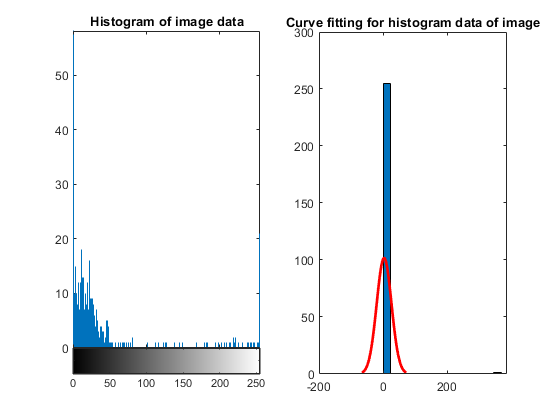

% histogram of image data
figure
figure(img+1)
%imhist(I) calculates the histogram for the grayscale image I. The imhist function returns the histogram counts in counts and the bin locations in binLocations.
subplot(1,2,1)
imhist(df1)
title('Histogram of image data')
imh1=imhist(df1);
% Do curve fitting (histfit) to the histogram line, thus we can substract edge value of the histogram
subplot(1,2,2)
hift1=histfit(imh1);
title('Curve fitting for histogram data of image')

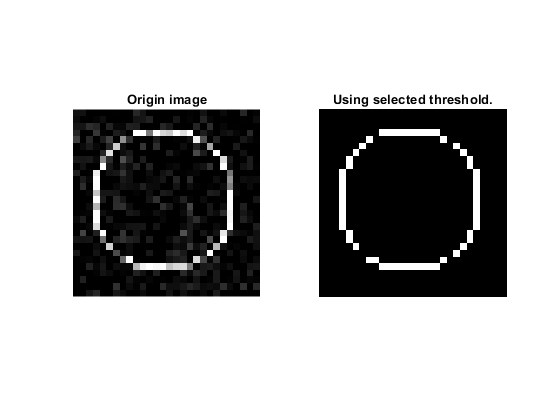


% from the histogram, the best threshoold can be taken:
hift1_max=max(hift1(2).YData); %substract line data only, and taking the maximum value


%Use selecting threshold and use as image filter
figure
figure(img+2)
% [valeyvalue, valyindex]=findpeaks(-imh1)
% figure
% % level = graythresh(df1)
% % df_bw = imbinarize(df1,level);
% figure(img+2)
threshold=round(hift1_max,-2);
df_bw =df1 > threshold;
subplot(1,2,1)
imshow(df1);title('Origin image')
subplot(1,2,2)
imshow(df_bw);title('Using selected threshold.')

% exportgraphics(figure(img+1),'Q1_result.jpg',"Resolution",150)

2. Calculate Hough transform to find the longest line in the mage.

[https://nl.mathworks.com/help/images/ref/imopen.html](https://nl.mathworks.com/help/images/ref/imopen.html)

`'Sobel','Prewitt','Roberts','log','zerocross','Canny','approxcanny'`

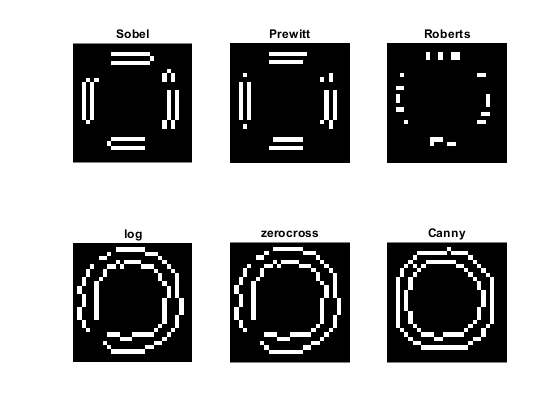

%extract edge of the image
figure
figure(img+3)
subplot(2,3,1)
edf1=imshow(edge(df1,'Sobel'));title('Sobel')
edf1=edge(df1,'Sobel');
subplot(2,3,2)
edf2=imshow(edge(df1,'Prewitt'));title('Prewitt')
subplot(2,3,3)
edf2=imshow(edge(df1,'Roberts'));title('Roberts')
subplot(2,3,4)
edf2=imshow(edge(df1,'log'));title('log')
subplot(2,3,5)
edf2=imshow(edge(df1,'zerocross'));title('zerocross')
subplot(2,3,6)
edf2=imshow(edge(df1,'canny_old'));title('Canny')

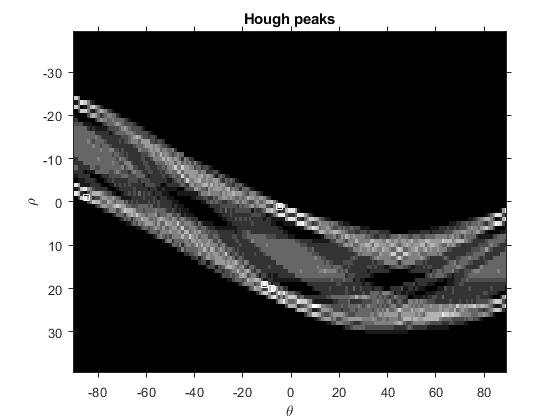


% 
% subplot(2,3,1)
% edf1=imshow(edge(df1,'Sobel'));
% 
% edf1=edge(df1,'Prewitt');
% figure
% figure(img+3)
% imshow(edf1)
% title('Edge image')

figure
figure(img+4)
[H,T,R]=hough(edf1);
imshow(H,[],'XData',T,'YData',R,...
            'InitialMagnification','fit');
xlabel('\theta'), ylabel('\rho');
axis on, axis normal, hold on;
title('Hough peaks')
% Find peaks 

P  = houghpeaks(H,4,'threshold',ceil(0.3*max(H(:))));
x = T(P(:,2)); y = R(P(:,1));
plot(x,y,'s','color','white');

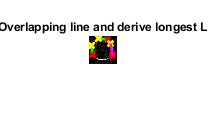




lines = houghlines(edf1,T,R,P,'FillGap',5,'MinLength',2);
figure, figure(img+4),imshow(df1), hold on
% 
% imshow(df1)
max_len = 0;
for k = 1:length(lines)
   xy = [lines(k).point1; lines(k).point2];
   plot(xy(:,1),xy(:,2),'LineWidth',2,'Color','green');

   % Plot beginnings and ends of lines
   plot(xy(1,1),xy(1,2),'x','LineWidth',2,'Color','yellow');
   plot(xy(2,1),xy(2,2),'x','LineWidth',2,'Color','red');

   % Determine the endpoints of the longest line segment
   len = norm(lines(k).point1 - lines(k).point2);
   if ( len > max_len)
      max_len = len;
      xy_long = xy;
   end
end
figure(img+5)
plot(xy_long(:,1),xy_long(:,2),'LineWidth',2,'Color','#FF00FF');
hold on
title('Overlapping line and derive longest L')


fprintf('Longest length');

Longest length

disp(len)

    9.0554



3. To find the area of the shape use morphological operators, and come to pixel number = area of the shape.

Pick a circle and a square figure.

% df1=im2bw(df1); figure, imshow(df1);title('binary the image')
% imshow(test)
% [centers, radii, metric]=imfindcircles(im2bw(test),[2,200],"Sensitivity",0.95)
% h = viscircles(centers,radii);
% im_enclose=imclearborder(~edf1,4); figure, %imshow(im_enclose);

% bwarea(im_enclose)
% sum(im_enclose,'all')

%if square

se=strel('line',28,28);
sq=imread(ds.Files{3});
afterOpening = imclose(sq,se);ara_1=im2bw(afterOpening);
area_im_1=sum(ara_1,'all')

area_im_1 = 89

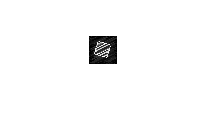

figure, imshow(afterOpening,[]);

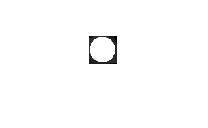


%if circle
se=strel('disk',100);
cir=imread(ds.Files{1});
afterOpening=imclose(cir,se);ara_2=im2bw(afterOpening);


imshow(afterOpening,[]);

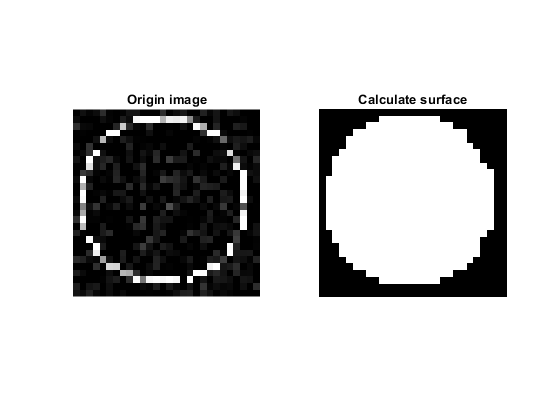

% org_cir=;
% cir_dis=cat(org_cir,Aftermsk_cir);

bi=(im2bw(afterOpening));

figure
figure(img+6)
subplot(1,2,1)
imshow(cir);title('Origin image')
subplot(1,2,2)
imshow(bi);title('Calculate surface')

area_im_2=sum(bi,'all')

area_im_2 = 511

4. Which dimensionless quantity is suitable to differentiate the two shapes?

Boundary line derive from Hough function : $L_{\textrm{Hline}}$

Area that derive from Hough line:${\textrm{Area}}_{\textrm{hough}}$

% % Function
function [img,bimg]=rdimg(file)
    ds = imageDatastore("Images\","FileExtensions",'.tiff');
    img=imread(ds.Files{file});
    bimg=im2bw(img);

end


